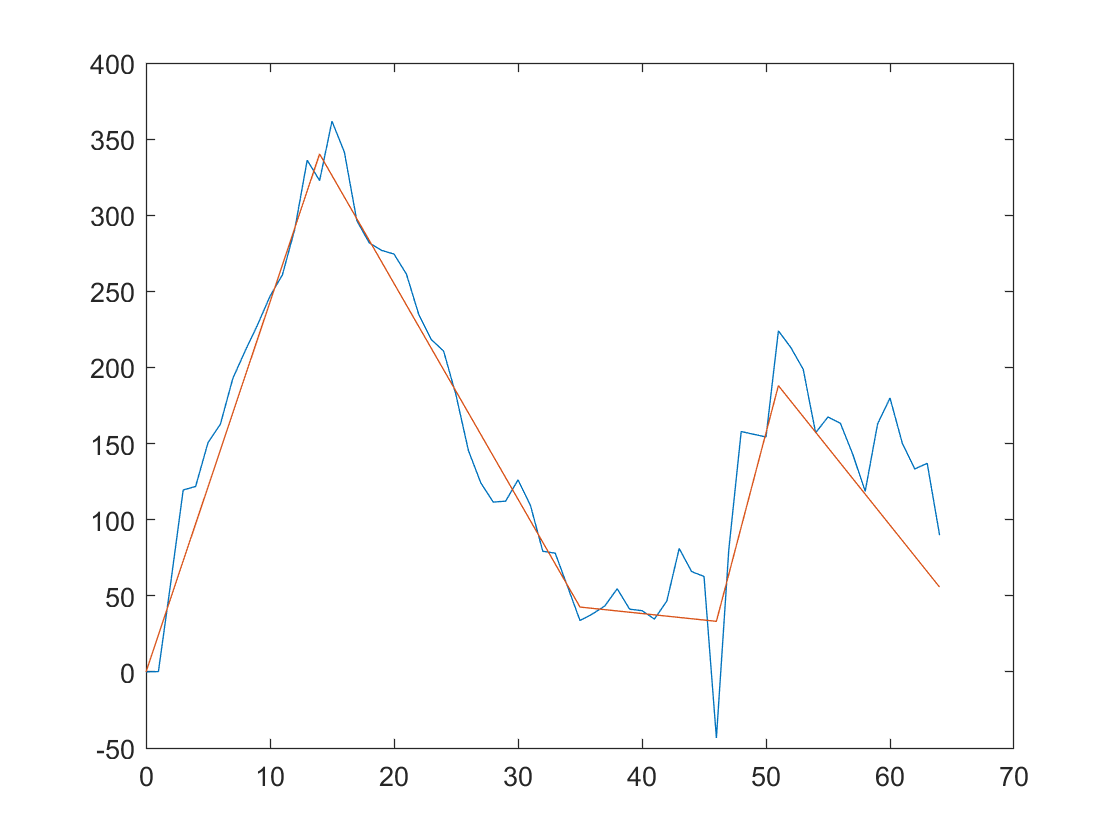

% plot line segment from autostepfinder parameters

interval = 1; % [s]

lineEqn = @(a,x) a(1) + a(2)*x;

speeds = [LevelBefore; LevelAfter(end)] / interval;
times = [xdat(1); TimeStep+xdat(1); xdat(end)];

v_seg=[]; b_seg=[]; Pos=[]; Time=[];
for ii = 1:length(times)-1
    
    t_seg = times(ii):interval:times(ii+1);
    v_seg(ii) = speeds(ii);
    if ii>1
        b_seg(ii) = (v_seg(ii-1)-v_seg(ii))*Time(end) + b_seg(ii-1);
    else
        b_seg(ii) = ydat(1) - v_seg(ii)*xdat(1);
    end
    
    Time = [Time t_seg];
    Pos = [Pos lineEqn([b_seg(ii) v_seg(ii)], t_seg)];

end

clf
plot(xdat,ydat)
hold on
plot(Time, Pos)